path = "FinalProjectBagOfWords\images\FinalProjectSpectrograms\PAD_ROIS\";
%Get DataStore of bird Region of Interests
birdROIs = imageDatastore(path,'IncludeSubfolders',true,'LabelSource','foldernames');

numBirdTypes = numel(categories(birdROIs.Labels));

%Split into training and test 
%200, 40
[birdTrain,birdTest] = splitEachLabel(birdROIs,30,10,'randomized');

I = readimage(birdROIs, 1);
[roiRows, roiCols, dim] = size(I);
roiRows = round(roiRows * 0.25);
roiCols = round(roiCols * 0.25);
%Choice of NeuralNetwork
%net = resnet18;
%  net = alexnet;
%net = googlenet;


%Get input size of net
netLayers = net.Layers;
inlayer = net.Layers(1);
insz = inlayer.InputSize;


numClasses = numel(categories(birdTrain.Labels));

% resnet18
% lgraph = layerGraph(net);
% 
% newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
% lgraph = replaceLayer(lgraph,'fc1000',newFCLayer);
% 
% newClassLayer = classificationLayer('Name','new_classoutput');
% lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',newClassLayer);

%googlenet
% lgraph = layerGraph(net);
% 
% newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
% lgraph = replaceLayer(lgraph,'loss3-classifier',newFCLayer);
% 
% newClassLayer = classificationLayer('Name','new_classoutput');
% lgraph = replaceLayer(lgraph,'output',newClassLayer);

%alexNet
% netLayers(end-2) = fullyConnectedLayer(numBirdTypes);
% netLayers(end) = classificationLayer;

%Augmented Images for PreEstablished Networks(googlenet, alexnet, resnet18)
% augBirdTest = augmentedImageDatastore([insz(1),insz(2)],birdTest);
% augBirdTrain = augmentedImageDatastore([insz(1),insz(2)],birdTrain);

%Augmented Images for customnet
augBirdTest = augmentedImageDatastore([roiRows, roiCols],birdTest);
augBirdTrain = augmentedImageDatastore([roiRows, roiCols],birdTrain);


%hyper parameters
% test perc = 1 - train

% verbose = false;
augmentedResolution = [roiRows roiCols]; 
inputResolution = augmentedResolution;
inputResolution(3) = 3; % color dimension, set to 1 for black/white images
layers = [imageInputLayer(inputResolution);
          convolution2dLayer(3,32,'Stride',1);
          batchNormalizationLayer(); 
          reluLayer();
          maxPooling2dLayer(1,'Stride',2);
          convolution2dLayer(3,64,'Stride',2);
          batchNormalizationLayer(); 
          reluLayer();
          maxPooling2dLayer(2,'Stride',2);
          dropoutLayer(0.5);
          fullyConnectedLayer(numClasses); 
          softmaxLayer();
          classificationLayer()];
      
options = trainingOptions('sgdm',... 
'MiniBatchSize', 10, ...
'MaxEpochs', 30, ... 
'LearnRateSchedule', 'piecewise', ...
'InitialLearnRate', 0.001, ...
'Shuffle',"once",...
'LearnRateDropPeriod', 5, ...
'LearnRateDropFactor', 0.2, ...
'L2Regularization', 0.0005, ...
'Momentum', 0.8, ...
'Verbose', false, ...
'VerboseFrequency', 10, ...
'ValidationFrequency', 20, ...
'ValidationData', augBirdTest, ...
'ValidationPatience',7, ...
"Plots","training-progress");
 

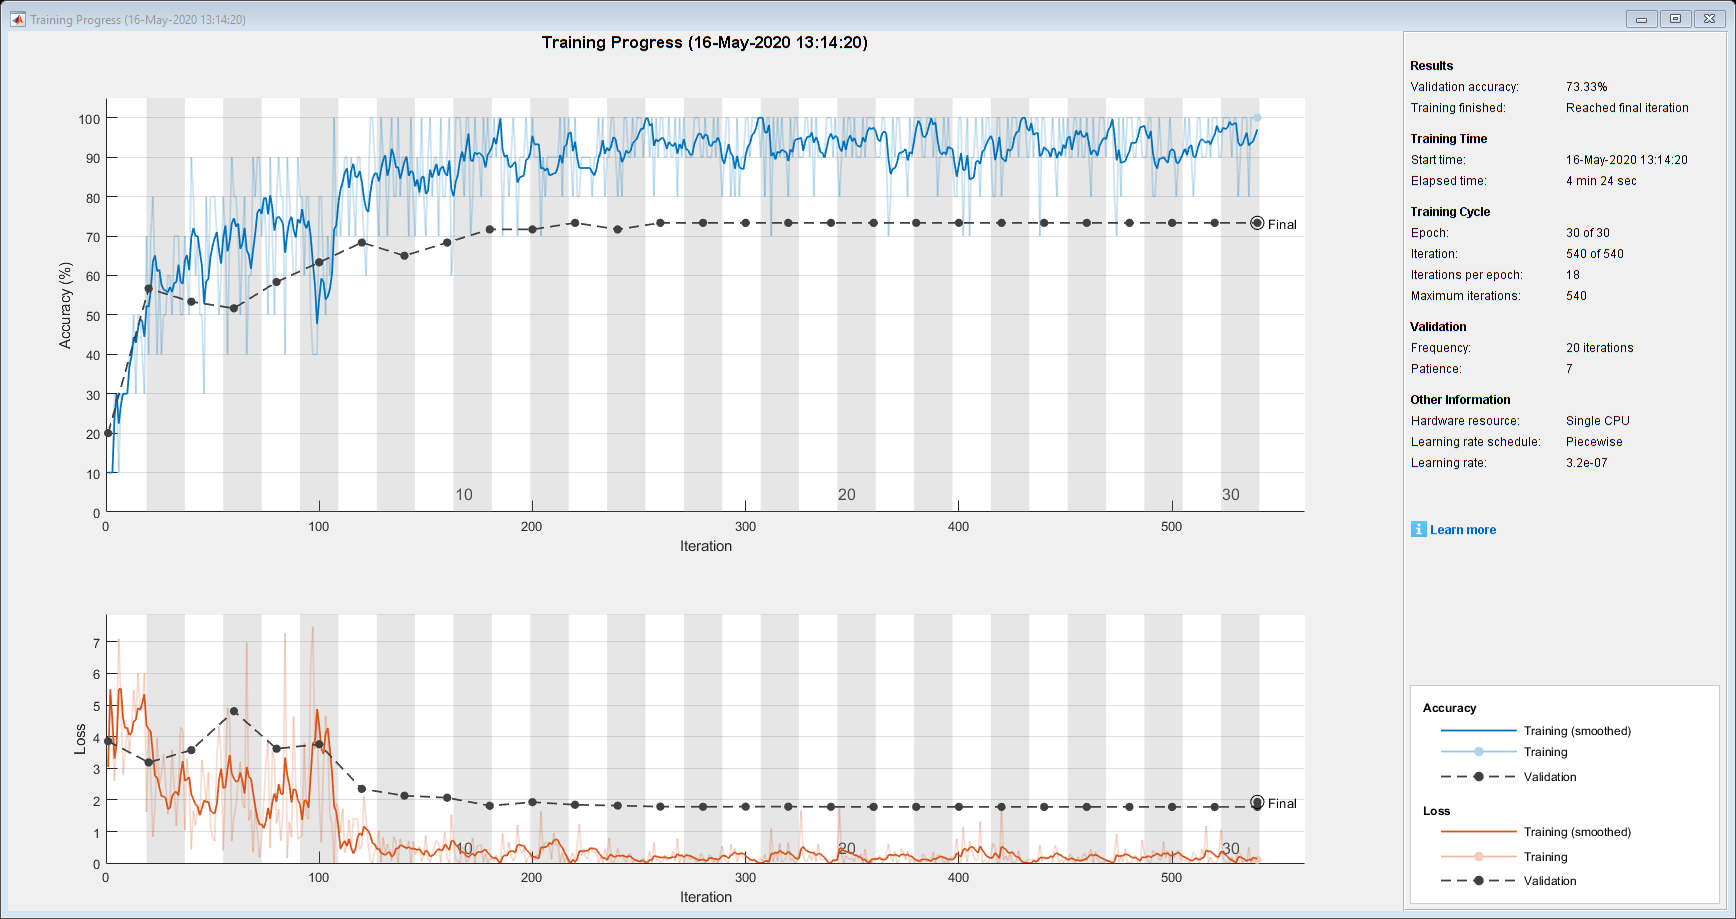


%Train Network
%[birdNet,info] = trainNetwork(birdTrain, layers, options);
[birdNet,info] = trainNetwork(augBirdTrain, layers, options);

analyzeNetwork(birdNet);

%Run network on test data
%birdTestPred = classify(birdNet,birdTest);
birdTestPred = classify(birdNet,augBirdTest);


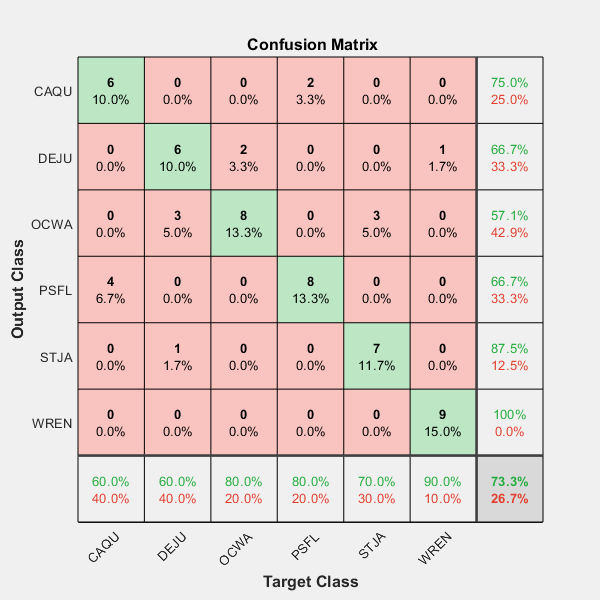

figure
%confusionchart(YTest,YPred);
cm = plotconfusion(birdTest.Labels, birdTestPred);

[cm, order] = confusionmat(birdTest.Labels, birdTestPred);
confMat = cm;
%fscore = zeros(size(confMat,1));
for i =1:size(confMat,1)
    recall =confMat(i,i)/sum(confMat(i,:));
    precision=confMat(i,i)/sum(confMat(:,i));
    f_score(i) = 2*recall*precision/(precision+recall);
end

%Show Accuracy
accuracy = sum(birdTestPred == birdTest.Labels)/numel(birdTest.Labels);

% %Create a network by modifying AlexNet
% 
% layers(end-2) = fullyConnectedLayer(numBirdTypes);
% layers(end) = classificationLayer;
% %Set training algorithm options
% 
% options = trainingOptions('sgdm','InitialLearnRate', 0.001);
%  
% %Perform training
% 
% [birdnet,info] = trainNetwork(augBirdTrain, layers, options);
%  
% %Use trained network to classify test images
% 
% testPreds = classify(birdnet,augBirdTest);
% %Training Option
% plot(info.TrainingLoss);
% 
% birdTestTypes = birdTest.Labels;
% numCorrect = nnz(testPreds == birdTestTypes);
% fracCorrect = numCorrect/numel(testPreds);
% confusionchart(birdTestTypes,testPreds);